filename = 'C:\Projects\arduino_adjustable_power_supply\Rev_B\Simulation\Stage_1_Boost_controller_test_inj_transformer.txt';
T1 = readtable(filename, 'VariableNamingRule','preserve')

T1 = 4001×2 table
    Freq.                        V(vout)/V(vinj)                   
    ______    _____________________________________________________

         1    {'(-5.14645514836999e+001dB,1.77884740202566e+002°)'}
    1.0023    {'(-5.14645789147521e+001dB,1.77879861088073e+002°)'}
    1.0046    {'(-5.14646064525417e+001dB,1.77876022573677e+002°)'}
    1.0069    {'(-5.14646341757098e+001dB,1.77869018640625e+002°)'}
    1.0093    {'(-5.14646620034193e+001dB,1.77863067277818e+002°)'}
    1.0116    {'(-5.14646899131377e+001dB,1.77860230465818e+002°)'}
    1.0139    {'(-5.14647180143559e+001dB,1.77853229511429e+002°)'}
    1.0162    {'(-5.14647461996840e+001dB,1.77849321574288e+002°)'}
    1.0186    {'(-5.14647745284350e+001dB,1.77844367884543e+002°)'}
    1.0209    {'(-5.14648030029957e+001dB,1.77838380300847e+002°)'}
    1.0233    {'(-5.14648315621114e+001dB,1.77835440623317e+002°)'}
    1.0257    {'(-5.146486028

V2c = cellfun(@(x)sscanf(x, '(%fdB,%f°'), T1.('V(vout)/V(vinj)'), 'Unif',0);
V2m = cell2mat(V2c')';
T2 = table('Size',[size(T1.('Freq.'),1) 3],'VariableTypes',{'double','double','double'}, 'VariableNames',{'FreqHz','MagndB','PhasDg'});
T2.FreqHz = T1.('Freq.');
T2.MagndB = V2m(:,1);
T2.PhasDg = V2m(:,2)

T2 = 4001×3 table
    FreqHz    MagndB     PhasDg
    ______    _______    ______

         1    -51.465    177.88
    1.0023    -51.465    177.88
    1.0046    -51.465    177.88
    1.0069    -51.465    177.87
    1.0093    -51.465    177.86
    1.0116    -51.465    177.86
    1.0139    -51.465    177.85
    1.0162    -51.465    177.85
    1.0186    -51.465    177.84
    1.0209    -51.465    177.84
    1.0233    -51.465    177.84
    1.0257    -51.465    177.83
     1.028    -51.465    177.82
    1.0304    -51.465    177.82
    1.0328    -51.465    177.81
    1.0351    -51.465    177.81


Mag = db2mag(T2.MagndB);
Phs = deg2rad(T2.PhasDg);
Rsp = Mag.*exp(1j*Phs)

Rsp =   -0.0027 + 0.0001i
  -0.0027 + 0.0001i
  -0.0027 + 0.0001i
  -0.0027 + 0.0001i
  -0.0027 + 0.0001i
  -0.0027 + 0.0001i
  -0.0027 + 0.0001i
  -0.0027 + 0.0001i
  -0.0027 + 0.0001i
  -0.0027 + 0.0001i


Sizes = [size(T2.FreqHz); size(Rsp)]

Sizes =         4001           1
        4001           1


sysfr = idfrd(Rsp,T2.FreqHz,0,'FrequencyUnit','Hz')   

sysfr =
IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s).
Response data is available at 4001 frequency points, ranging from 1 Hz to 1e+04 Hz.
 
Status:                                                         
Created by direct construction or transformation. Not estimated.


sys_ss = ssest(sysfr, 1)       

sys_ss =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
           x1
   x1  -170.1
 
  B = 
        u1
   x1  0.5
 
  C = 
            x1
   y1  -0.9091
 
  D = 
       u1
   y1   0
 
  K = 
       y1
   x1   0
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: none
   Number of free coefficients: 3
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using SSEST on frequency response data "sysfr".
Fit to estimation data: 99.71%                           
FPE: 1.191e-11, MSE: 1.19e-11                            


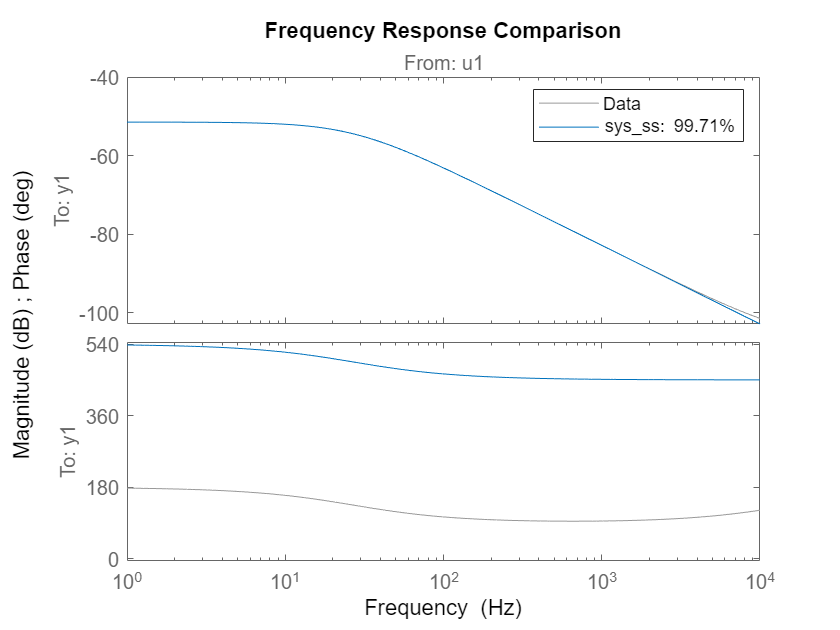

figure
compare(sysfr, sys_ss)